% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

%ex3.1.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F3;F4]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.1068
    3.6822
    2.3787
    2.2157


ys = FourTankSystemSensor(xs,p)

ys =   108.0357
   96.8675
   62.5759
   58.2863


zs = FourTankSystemOutput(xs,p)

zs =   108.0357
   96.8675


%ex3.4.1 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0069         0    0.0090         0
         0   -0.0073         0    0.0094
         0         0   -0.0090         0
         0         0         0   -0.0094


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Czss=Css(1:2,:)

Czss =     0.0026         0         0         0
         0    0.0026         0         0


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0


Dzss=Dss(1:2,:)

Dzss =      0     0
     0     0


sys_ss=ss(Ass,Bss,Czss,Dzss)

sys_ss =
 
  A = 
              x1         x2         x3         x4
   x1  -0.006879          0   0.009038          0
   x2          0  -0.007265          0   0.009365
   x3          0          0  -0.009038          0
   x4          0          0          0  -0.009365
 
  B = 
         u1    u2
   x1  0.45     0
   x2     0   0.4
   x3     0   0.6
   x4  0.55     0
 
  C = 
             x1        x2        x3        x4
   y1  0.002631         0         0         0
   y2         0  0.002631         0         0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



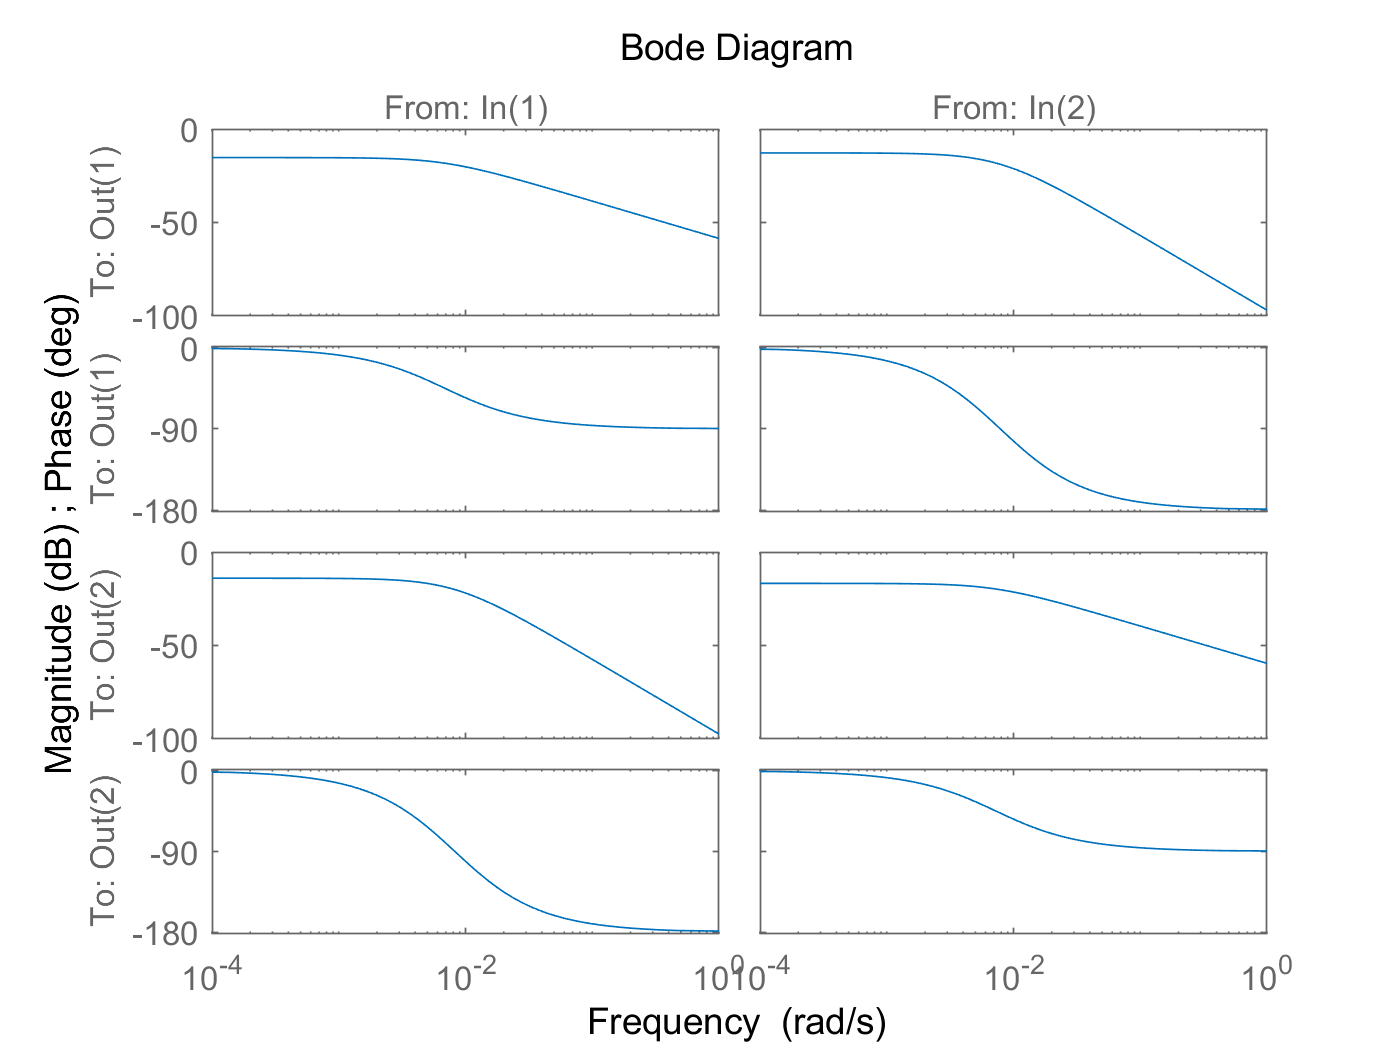

bode(sys_ss)